# HW3 Program Assignment

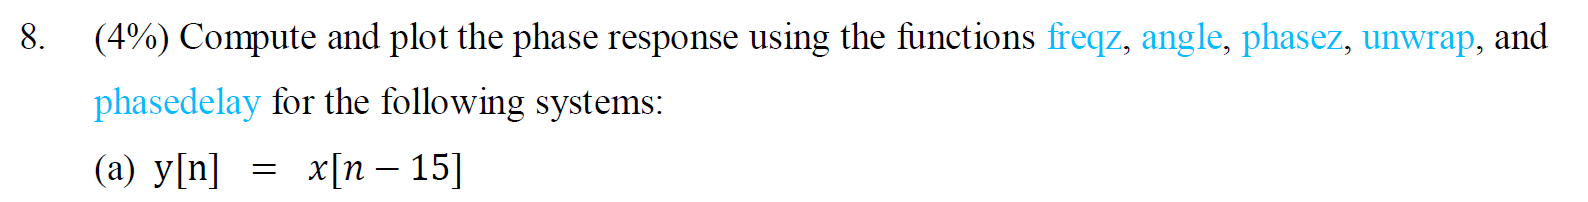

### (a)

### 
$$Y\left(e^{j\omega } \right)=e^{-j15\omega } X\left(e^{j\omega } \right)\Rightarrow H\left(e^{j\omega } \right)=\frac{Y\left(e^{j\omega } \right)}{X\left(e^{j\omega } \right)}=e^{-15j\omega }$$
 

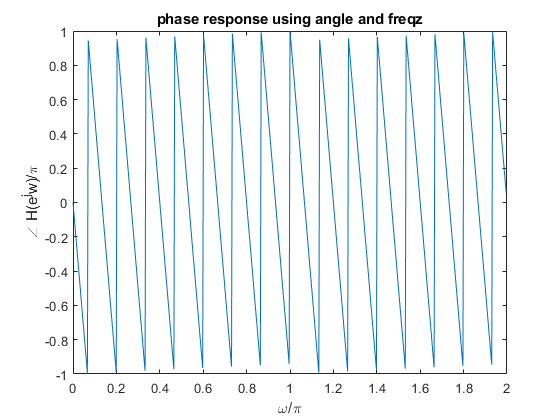

b = zeros(1, 16);
b(16) = 1;
a = zeros(1, 16);
a(1) = 1;

%freqz
[h, w] = freqz(b, a, 'whole');
%h = fftshift(h);
%w = fftshift(w);
plot(w/pi, angle(h)/pi);
title('phase response using angle and freqz')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

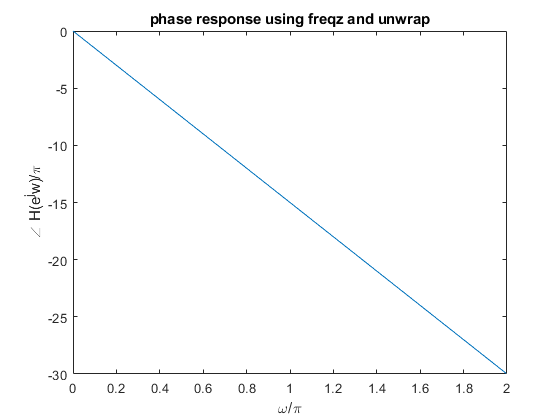


%unwrap
plot(w/pi, unwrap(angle(h))/pi);
title('phase response using freqz and unwrap')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

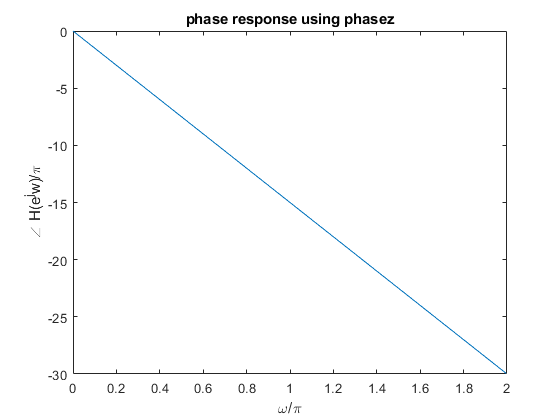


%phasez
[phi, w] = phasez(b, a, 'whole');
plot(w/pi, phi/pi);
title('phase response using phasez')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

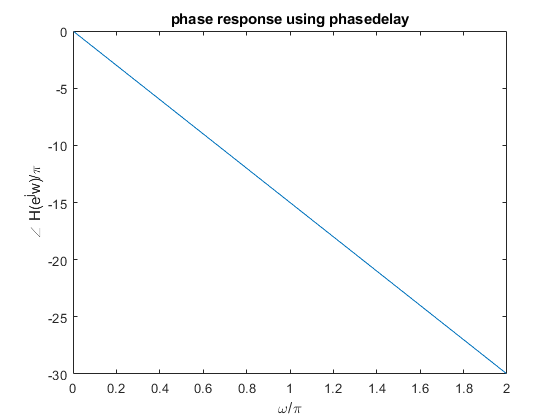


%phasedelay
[phi, w] = phasedelay(b, a, 'whole');
phi = -phi.*w;
plot(w/pi, phi/pi);
title('phase response using phasedelay')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

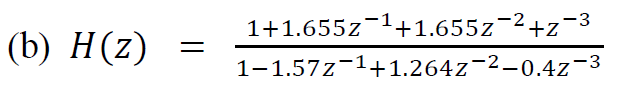

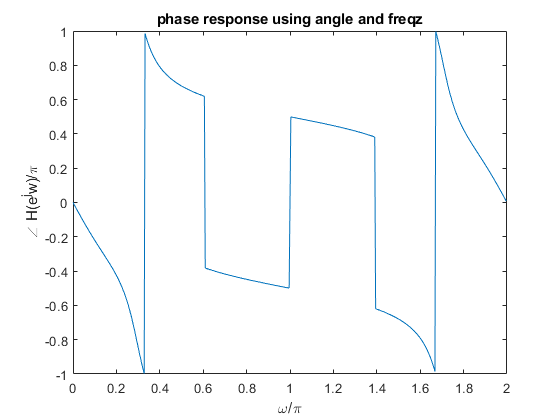

b = [1 1.655 1.655 1];
a = [1 -1.57 1.264 -0.4];
%freqz
[h, w] = freqz(b, a, 'whole');
plot(w/pi, angle(h)/pi);
title('phase response using angle and freqz')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

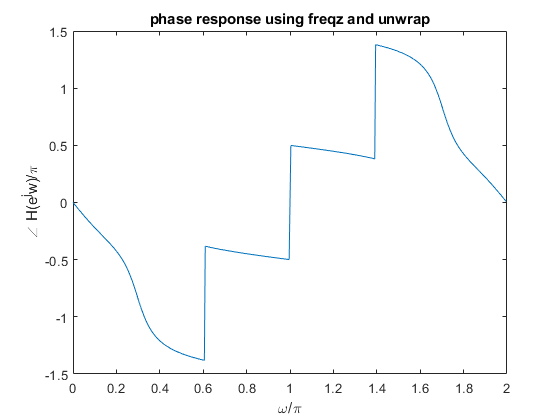


%unwrap
plot(w/pi, unwrap(angle(h))/pi);
title('phase response using freqz and unwrap')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

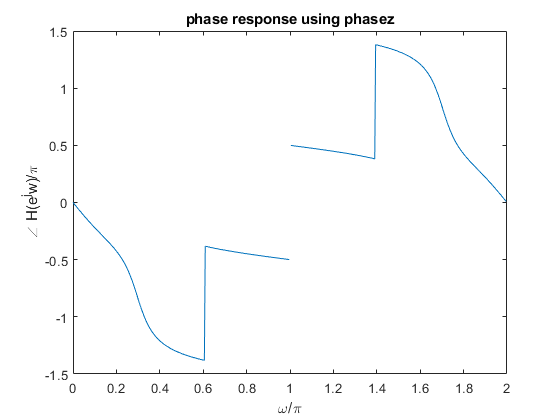


%phasez
[phi, w] = phasez(b, a, 'whole');
plot(w/pi, phi/pi);
title('phase response using phasez')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

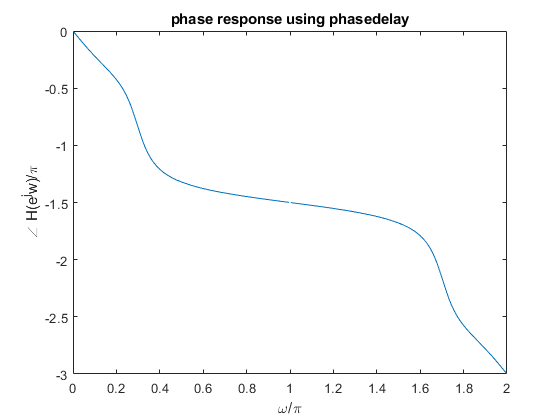


%phasedelay
[phi, w] = phasedelay(b, a, 'whole');
phi = -phi.*w;
plot(w/pi, phi/pi);
title('phase response using phasedelay')
xlabel('\omega/\pi');
ylabel('\angle H(e^jw)/\pi');

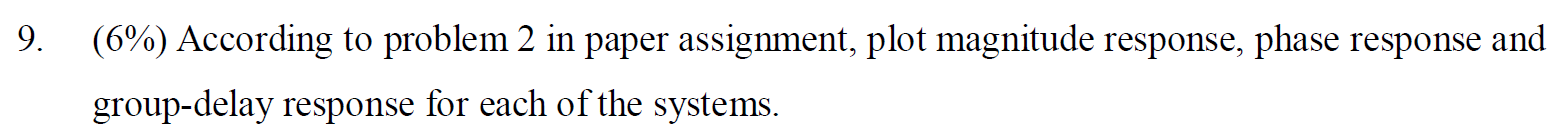

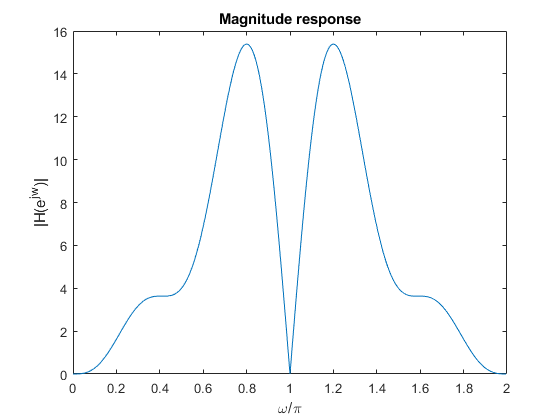

b = [1 -2 3 -4 0 4 -3 2 -1];
a = [1 0 0 0 0 0 0 0 0];
[h, w] = freqz(b, a, 'whole');
plot(w/pi, abs(h));
title('Magnitude response');
xlabel('\omega/\pi');
ylabel('|H(e^{jw})|');

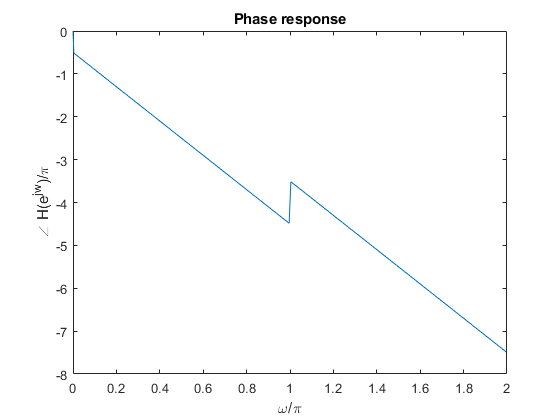

phase_h = unwrap(angle(h));
plot(w/pi, phase_h/pi);
title('Phase response');
xlabel('\omega/\pi');
ylabel('\angle H(e^{jw})/\pi');

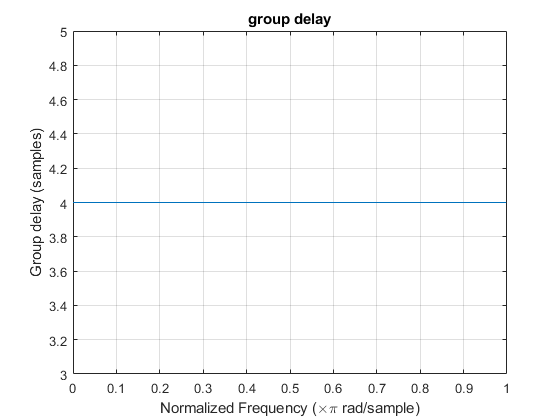

%zplane(b, a);
%[gd,w] = grpdelay(b, a);
grpdelay(b, a);      
title('group delay');

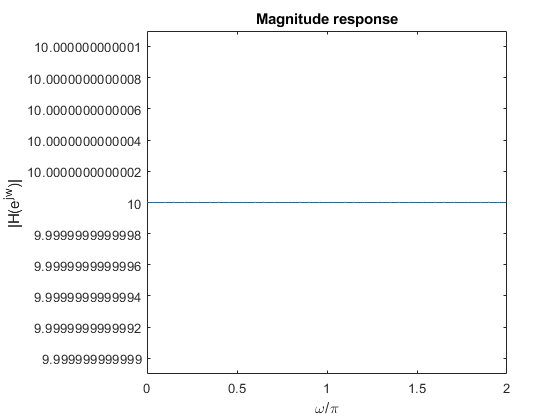

b = zeros(1, 11);
b(11) = 10;
a = [1];
[h, w] = freqz(b, a, 'whole');
plot(w/pi, abs(h));
title('Magnitude response');
xlabel('\omega/\pi');
ylabel('|H(e^{jw})|');

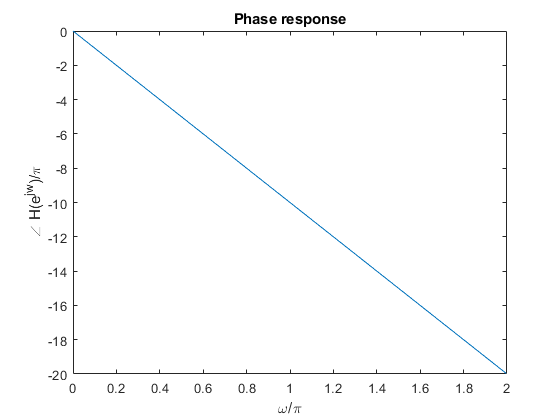

phase_h = unwrap(angle(h));
plot(w/pi, phase_h/pi);
title('Phase response');
xlabel('\omega/\pi');
ylabel('\angle H(e^{jw})/\pi');

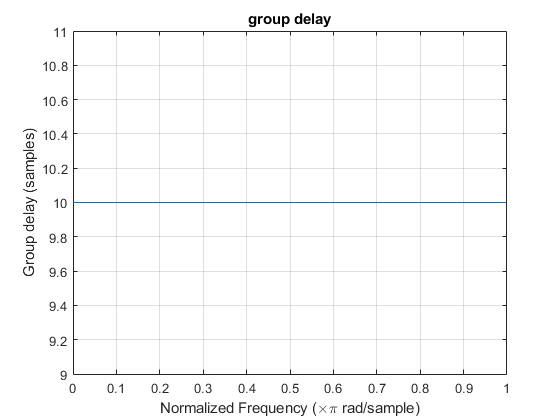

grpdelay(b, a);      
title('group delay');

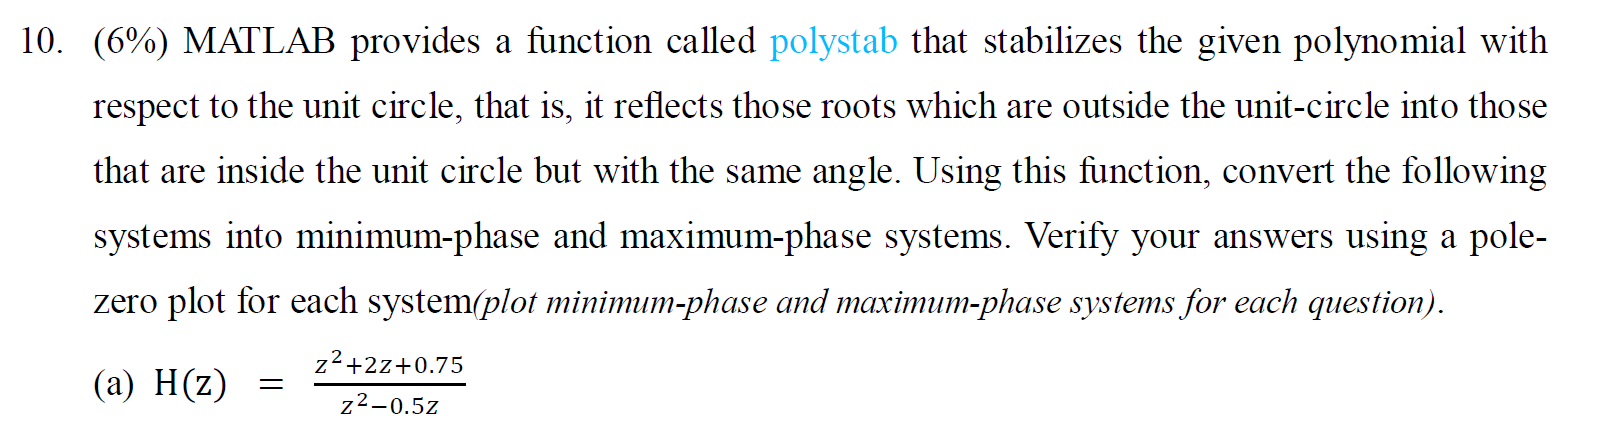

            H(z)$=\frac{1+2z^{-1} +0\ldotp 75z^{-2} }{1-0\ldotp 5z^{-1} }$             

num = [1, 2, 0.75];
denom = [1, -0.5];
num_min = polystab(num)*norm(num)/norm(polystab(num));
denom_min = polystab(denom)*norm(denom)/norm(polystab(denom));
% num_min = polystab(num);
% denom_min = polystab(denom);
isminphase(num_min, denom_min)

ans = logical
   1


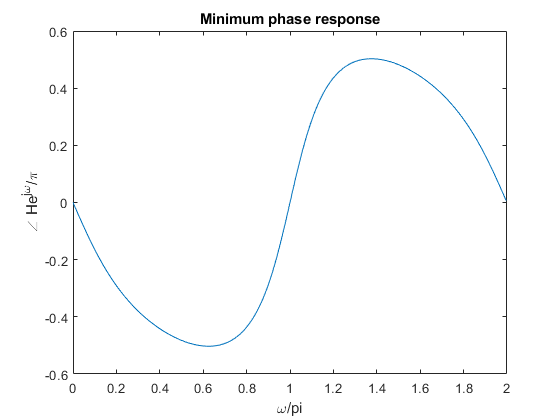

[h_min, w] = freqz(num_min, denom_min, 'whole');
h_min_Un = unwrap(angle(h_min));
plot(w/pi, h_min_Un/pi);
title('Minimum phase response');
xlabel('\omega/pi');
ylabel('\angle He^{j\omega}/\pi');

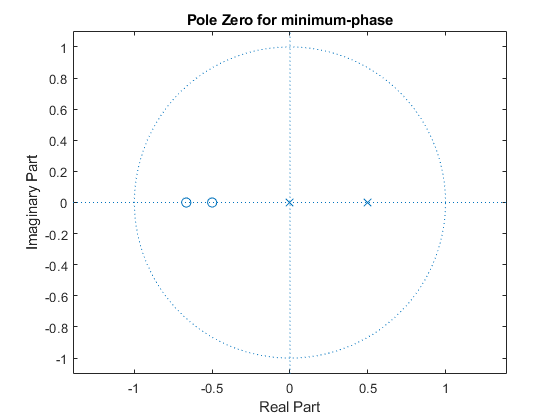

%hmin = polystab(h);
[p, z] = pzmap(num_min, denom_min);
zplane(num_min, denom_min);
title('Pole Zero for minimum-phase');

According to the pole zero diagram, all of poles and zeros are inside the unit circle. Hence, H(z) has been converted to a minimum phase system.

z_max = 1./z;
p_max = p;
[b, a] = zp2tf(z_max, p_max, 1);
ismaxphase(b, a)

ans = logical
   1


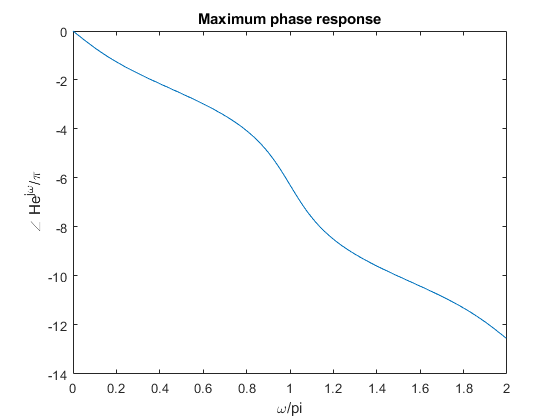

[h_max, w] = freqz(b, a, 'whole');
h_max_Un = unwrap(angle(h_max));
plot(w/pi, h_max_Un);
title('Maximum phase response');
xlabel('\omega/pi');
ylabel('\angle He^{j\omega}/\pi');

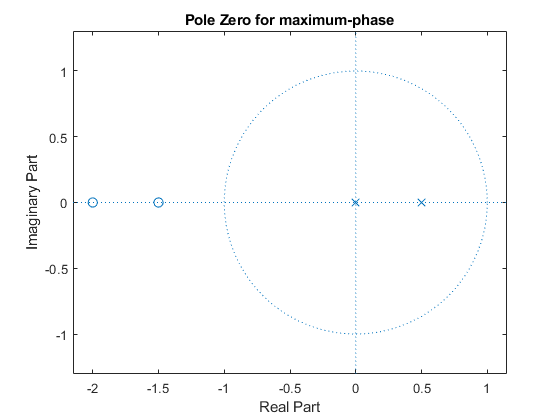

zplane(b, a);
title('Pole Zero for maximum-phase');

According to the pole zero diagram, all of zeros are outside the unit circle. Hence, H(z) has been converted to a maximum phase system.

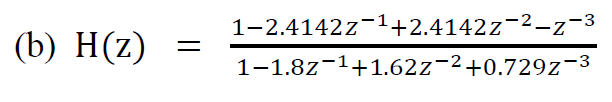

num = [1 -2.4142 2.4142 -1];
denom = [1 -1.8 1.62 0.729];
num_min = polystab(num)*norm(num)/norm(polystab(num));
denom_min = polystab(denom)*norm(denom)/norm(polystab(denom));
% num_min = polystab(num)/(polystab(num));
% denom_min = polystab(denom)/(polystab(denom));
isminphase(num_min, denom_min)

ans = logical
   1


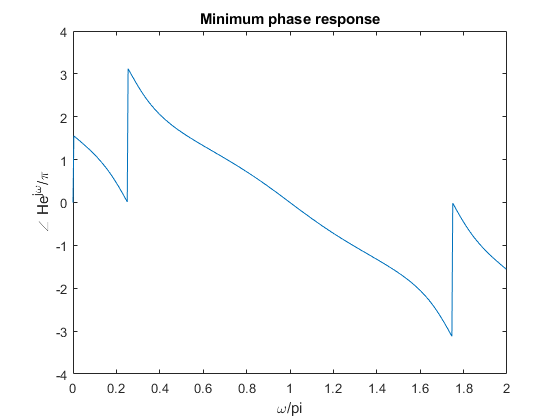

[h_min, w] = freqz(num_min, denom_min, 'whole');
h_min_Un = unwrap(angle(h_min));
plot(w/pi, h_min_Un);
title('Minimum phase response');
xlabel('\omega/pi');
ylabel('\angle He^{j\omega}/\pi');

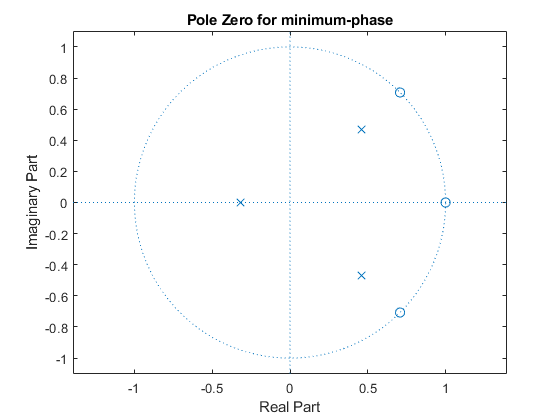

[p, z] = pzmap(num_min, denom_min);
zplane(num_min, denom_min);
title('Pole Zero for minimum-phase');

According to the pole zero diagram, all of poles  are inside the unit circle and zeros are on the unit circle. Hence, H(z) has been converted to a minimum phase system.

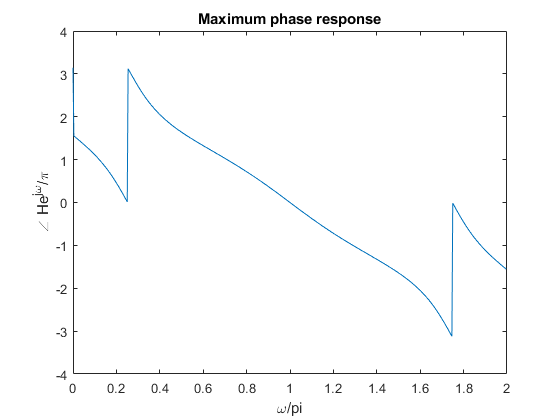

z_max = 1./z;
p_max = p;
[b, a] = zp2tf(z_max, p_max, 1);
[h_max, w] = freqz(b, a, 'whole');
h_max_Un = unwrap(angle(h_max));
plot(w/pi, h_max_Un);
title('Maximum phase response');
xlabel('\omega/pi');
ylabel('\angle He^{j\omega}/\pi');

ismaxphase(b, a)

ans = logical
   1


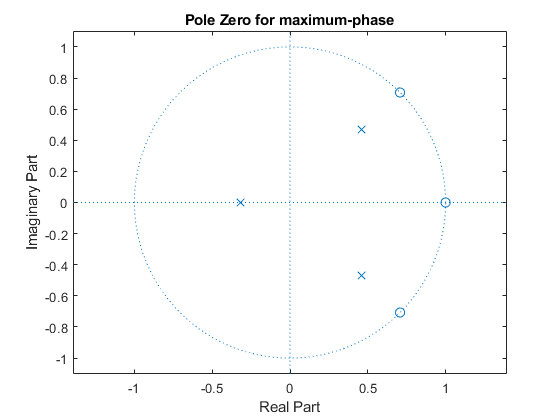

zplane(b, a);
title('Pole Zero for maximum-phase');

According to the pole zero diagram, all  zeros are on the unit circle. Hence, H(z) has been converted to a maximum phase system.

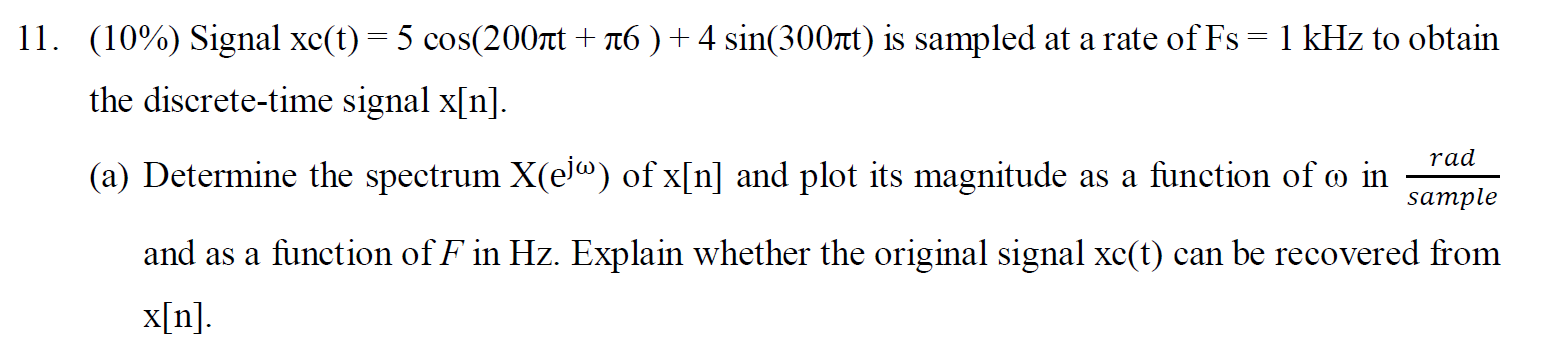

### 
$$\begin{array}{l}
{\textrm{CTFT}:\;e}^{j\Omega_0 t} \to 2\pi \delta \left(\Omega -\Omega_0 \right)\\
X\left(e^{j\omega } \right)=\frac{1}{T}\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=1000\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=1000\sum_{k=-\infty }^{k=\infty } 5\pi e^{j\pi /6} \delta \left(1000\omega -2000\pi k-200\pi \right)+\\
1000\sum_{k=-\infty }^{k=\infty } 5\pi e^{-j\pi /6} \delta \left(1000\omega -2000\pi k+200\pi \right)+1000\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(1000\omega -2000\pi k+200\pi \right)\\
-1000\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(1000\omega -2000\pi k-200\pi \right)
\end{array}$$


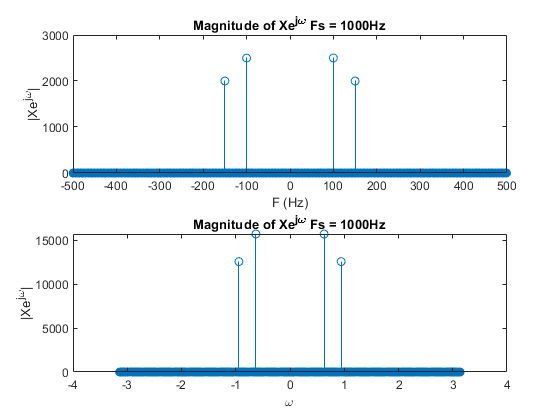

Fs = 1000;
t = 0:1/Fs:1-(1/Fs);
N = length(t);

xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
X = dtfs(xc);
freq = -500:(Fs/length(X)):500-(Fs/length(X));
subplot(2,1,1);
stem(freq, Fs*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 1000Hz');
xlabel('F (Hz)');
ylabel('|Xe^{j\omega}|');
subplot(2,1,2);
w = 2*pi*freq/Fs;
stem(w, Fs*2*pi*abs(fftshift(X)));    % note that *2*pi 
title('Magnitude of Xe^{j\omega} Fs = 1000Hz');
xlabel('\omega');
ylabel('|Xe^{j\omega}|');

### Fs = 1000Hz, $F_H =$150Hz < $\frac{F_s }{2}\Longrightarrow \mathrm{can}\;\mathrm{be}\;\mathrm{recovered}$

### 
$$X\left(e^{j\omega } \right)=\frac{1}{T}\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=500\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=500\sum_{k=-\infty }^{k=\infty } 5\pi e^{j\pi /6} \delta \left(500\omega -1000\pi k-200\pi \right)+$$


### 
$$\begin{array}{l}
500\sum_{k=-\infty }^{k=\infty } 5\pi e^{-j\pi /6} \delta \left(500\omega -1000\pi k+200\pi \right)+500\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(500\omega -1000\pi k+200\pi \right)\\
-500\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(500\omega -1000\pi k-200\pi \right)
\end{array}$$


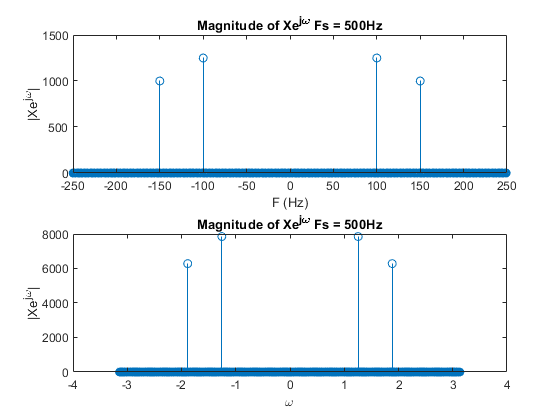

Fs = 500;
t = 0:1/Fs:1-(1/Fs);
%N = length(t);

xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
X = dtfs(xc);
freq = -250:(Fs/length(X)):250-(Fs/length(X));
figure;
subplot(2, 1, 1);
stem(freq, Fs*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 500Hz');
xlabel('F (Hz)');
ylabel('|Xe^{j\omega}|');
subplot(2, 1, 2);
w = 2*pi*freq/Fs;
stem(w, Fs*2*pi*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 500Hz');
xlabel('\omega');
ylabel('|Xe^{j\omega}|');

### Fs = 500Hz, $F_H$ = 150Hz < $\frac{F_s }{2}$

### 
$$X\left(e^{j\omega } \right)=\frac{1}{T}\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=100\sum_{k=-\infty }^{k=\infty } X_c \left(j\left(\frac{\omega }{T}-2\frac{\pi }{T}k\right)\right)=100\sum_{k=-\infty }^{k=\infty } 5\pi e^{j\pi /6} \delta \left(100\omega -200\pi k-200\pi \right)+$$


### 
$$\begin{array}{l}
100\sum_{k=-\infty }^{k=\infty } 5\pi e^{-j\pi /6} \delta \left(100\omega -200\pi k+200\pi \right)+100\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(100\omega -200\pi k+200\pi \right)\\
-100\sum_{k=-\infty }^{k=\infty } 4\pi j\delta \left(100\omega -200\pi k-200\pi \right)
\end{array}$$


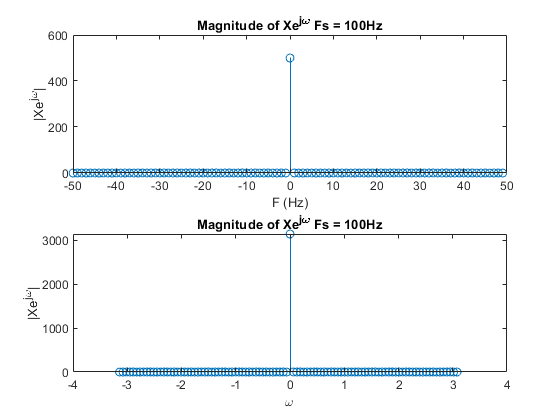

Fs = 100;
t = 0:1/Fs:1-(1/Fs);
N = length(t)/20;     %as period is 1/50 and 1s is 20

xc = 5*cos(200*pi*t + 6*pi) + 4*sin(300*pi*t);
X = dtfs(xc);
freq = -50:(Fs/length(X)):50-(Fs/length(X));
figure;
subplot(2, 1, 1);
stem(freq, Fs*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 100Hz');
xlabel('F (Hz)');
ylabel('|Xe^{j\omega}|');
subplot(2, 1, 2);
w = 2*pi*freq/Fs;
stem(w, Fs*2*pi*abs(fftshift(X)));
title('Magnitude of Xe^{j\omega} Fs = 100Hz');
xlabel('\omega');
ylabel('|Xe^{j\omega}|');

### Fs = 100Hz, $F_H$ = 150Hz > $\frac{F_s }{2}$ $\Longrightarrow$Cannot be recovered

### According to sampling theorem, bandwidth of sampled signal ($F_H$) has to be less than half of sampling frequency ($F_s$) so

### that the signal cae be recovered. And $F_H$ is 150Hz. Therefore, only when Fs > 2$\times$150=300Hz, the signal can be recovered.

### Hence, (c) Fs = 100Hz, sampled signal contains only DC value (only $\omega$=0 has value) in frequency domain, which can not be recovered!